Read the Audio file and plot

% Read the .wav file
[file, path] = uigetfile('a.wav', 'C:\Users\Raveen\Audio-Signal-Processing---Respeaker-Microphone-Array');
filePath = fullfile(path, file);
[audioData, sampleRate] = audioread(filePath);

% Create a time vector
timeVector = (0:length(audioData)-1) / sampleRate;

% Plot the audio waveform
figure;
plot(timeVector, audioData);
xlabel('Time (s)');
ylabel('Amplitude');
title(['Waveform of ', file]);
grid on;

% Frequency Domain Plot
N = length(audioData);                  % Number of samples
Y = fft(audioData);                     % Perform FFT
f = (0:N-1) * (sampleRate / N);         % Frequency vector
magnitude = abs(Y) / N;                 % Magnitude spectrum

% Plot the positive frequencies only
subplot(2,1,2);
plot(f(1:N/2), magnitude(1:N/2));       % Plot up to Nyquist frequency
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain');
grid on;

Create single frequency tone

% Parameters
frequency = 2000;       % Frequency in Hz (e.g., 440 Hz for A4 note)
duration = 10;          % Duration in seconds
sampleRate = 16000;     % Sampling rate in Hz (standard for audio) 44100

% Time vector
t = 0:1/sampleRate:duration; % Time vector from 0 to duration with step 1/sampleRate

% Generate sine wave
audioSignal = sin(2 * pi * frequency * t);

% Play the audio
%sound(audioSignal, sampleRate);

% Save the audio to a .wav file
audiowrite('sample_audio.wav', audioSignal, sampleRate);

% Plot the sine wave
figure;
plot(t(1:1000), audioSignal(1:1000)); % Plot the first 1000 samples for clarity
xlabel('Time (s)');
ylabel('Amplitude');
title(['Sine Wave at ', num2str(frequency), ' Hz']);
grid on;

Plot the recorded audio file

% Read the .wav file
[file, path] = uigetfile('sample.wav', 'C:\Users\Raveen\Audio-Signal-Processing---Respeaker-Microphone-Array');
filePath = fullfile(path, file);
[audioData, sampleRate] = audioread(filePath);

% Create a time vector
timeVector = (0:length(audioData)-1) / sampleRate;

% Plot the audio waveform
figure;
plot(timeVector, audioData);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of recorded (sample.wav)');
grid on;

% Frequency Domain Plot
N = length(audioData);                  % Number of samples
Y = fft(audioData);                     % Perform FFT
f = (0:N-1) * (sampleRate / N);         % Frequency vector
magnitude = abs(Y) / N;                 % Magnitude spectrum

% Plot the positive frequencies only
subplot(2,1,2);
plot(f(1:N/2), magnitude(1:N/2));       % Plot up to Nyquist frequency
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - Recorded signal(sample.wav)');
grid on;

Extract the 2000Hz frequency

% Load the audio signal from the .wav file
[inputSignal, Fs] = audioread('Single_Frequency\sample.wav'); % Read the audio file
%inputSignal = inputSignal(:, 1);            % Use only the first channel if stereo

% Define High-Pass Filter Parameters
cutoffFreq = 2000;          % Desired cutoff frequency in Hz
order = 6;                  % Filter order (higher = steeper cutoff)

% Design High-Pass Filter
highPassFilter = designfilt('highpassiir', 'FilterOrder', order, ...
    'HalfPowerFrequency', cutoffFreq, 'SampleRate', Fs);

% Apply the Filter to the Input Signal
filteredSignal = filtfilt(highPassFilter, inputSignal); % Zero-phase filtering

% Frequency Domain Analysis
N = length(inputSignal);                  % Length of the input signal
f = (0:N-1) * (Fs / N);                   % Frequency vector
magnitudeInput = abs(fft(inputSignal)) / N;     % FFT of original signal
magnitudeFiltered = abs(fft(filteredSignal)) / N; % FFT of filtered signal

% Save the Combined Signal to a New .wav File
audiowrite('filtered_audio.wav', filteredSignal, Fs);
disp('Combined audio file saved as filtered_audio.wav');


% Plot Results
figure;

% Time Domain: Original Signal
subplot(4,1,1);
plot((0:N-1)/Fs, inputSignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal (Time Domain)');
grid on;

% Time Domain: Filtered Signal
subplot(4,1,2);
plot((0:N-1)/Fs, filteredSignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Time Domain)');
grid on;

% Frequency Domain: Comparison
subplot(4,1,3);
plot(f(1:N/2), magnitudeInput(1:N/2), 'b', 'DisplayName', 'Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - original');
grid on;

subplot(4,1,4);
plot(f(1:N/2), magnitudeFiltered(1:N/2), 'b', 'DisplayName', 'Filtered');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain- filtered');
legend;
grid on;

plotting same graph

% Load the Recorded Signal
[recordedAudio, Fs1] = audioread('Single_Frequency\sample.wav'); % Read the audio file
[playedAudio, Fs] = audioread('Single_Frequency\sample_audio.wav'); % Read the audio file
%inputSignal = inputSignal(:, 1);            % Use only the first channel if stereo

% Define High-Pass Filter Parameters
cutoffFreq = 2000;          % Desired cutoff frequency in Hz
order = 6;                  % Filter order (higher = steeper cutoff)

% Design High-Pass Filter
highPassFilter = designfilt('highpassiir', 'FilterOrder', order, ...
    'HalfPowerFrequency', cutoffFreq, 'SampleRate', Fs);

% Apply the Filter to the Input Signal
filteredSignal = filtfilt(highPassFilter, inputSignal); % Zero-phase filtering

% Time Vector for Plotting
tPlayed = (0:length(playedAudio)-1) / Fs;     % Time vector for recorded signal
tRecorded = (0:length(recordedAudio)-1) / Fs1;  % Time vector for filtered signal

% Plot the Recorded and Generated Signals
figure;

% Original Signal
plot(tPlayed, playedAudio, 'b', 'LineWidth', 1.2, 'DisplayName', 'Played Signal');
hold on;

% Filtered Signal
plot(tRecorded, recordedAudio, 'r--', 'LineWidth', 1.2, 'DisplayName', 'Recorded Signal');
hold off;

% Add Labels and Legends
xlabel('Time (s)');
ylabel('Amplitude');
title('Recorded Signal and Played Signal Comparison');
grid on;


Plot the filtered signal and played signal

tFiltered = (0:length(filteredSignal)-1) / Fs1;

plot(tPlayed, playedAudio, 'b', 'LineWidth', 1.2, 'DisplayName', 'Played Signal');
hold on;

% Filtered Signal
plot(tFiltered, filteredSignal, 'r--', 'LineWidth', 1.2, 'DisplayName', 'Filtered Signal');
hold off;

% Add Labels and Legends
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Recorded Signal and Played Signal Comparison');
grid on;

Plot the 10 levels  of played volumes level -  recorded signals

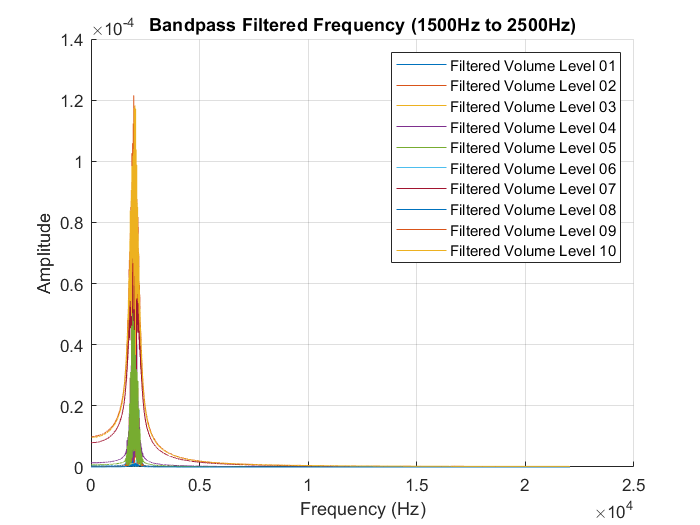

% Parameters
folderPath = 'second_test';        % Path to the folder containing audio files
Fs = 44100;                       % Sampling rate (Hz), adjust if needed
numSamples = 10;                  % Number of recorded signals
N = 44100;                        % Number of samples to analyze (1 second at 44.1 kHz)
lowCutoff = 1950;                 % Lower cutoff frequency (Hz)
highCutoff = 2050;                % Upper cutoff frequency (Hz)

% Design a Bandpass Filter
bpFilter = designfilt('bandpassfir', ...
                      'StopbandFrequency1', lowCutoff - 500, ...
                      'PassbandFrequency1', lowCutoff, ...
                      'PassbandFrequency2', highCutoff, ...
                      'StopbandFrequency2', highCutoff + 500, ...
                      'StopbandAttenuation1', 60, ...
                      'StopbandAttenuation2', 60, ...
                      'PassbandRipple', 1, ...
                      'SampleRate', Fs);

% Initialize Variables for FFT
frequency = (0:N/2-1) * (Fs / N); % Frequency vector for FFT

% Create a Figure for Plotting
figure;
hold on;

% Loop Through Each Audio File
for i = 1:numSamples
    % Generate the Full File Path
    fileName = sprintf('sample%02d_record.wav', i);
    filePath = fullfile(folderPath, fileName);
    
    % Check if the File Exists
    if ~isfile(filePath)
        fprintf('File "%s" not found. Skipping...\n', filePath);
        continue;
    end
    
    % Load the Audio File
    [signal, Fs] = audioread(filePath);
    
    % Use Only the First N Samples or Adjust Length if Necessary
    signal = signal(1:min(N, length(signal)), 1); % First channel only, if stereo
    
    % Apply Bandpass Filter
    filteredSignal = filtfilt(bpFilter, signal); % Zero-phase filtering
    
    % Compute FFT for Filtered Signal
    fftFiltered = abs(fft(filteredSignal, N)) / N; 
    
    % Plot Frequency Spectrum of Filtered Signal
    plot(frequency, fftFiltered(1:N/2), 'DisplayName', sprintf('Filtered Volume Level %02d', i));
    
    % Optionally, Save Filtered Signal to New File
    outputFileName = sprintf('filtered_bandpass_sample%02d_record.wav', i);
    outputFilePath = fullfile(folderPath, outputFileName);
    audiowrite(outputFilePath, filteredSignal, Fs);
end

% Add Labels, Title, and Legend
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Bandpass Filtered Frequency (1500Hz to 2500Hz)');
legend('show');
grid on;

hold off;

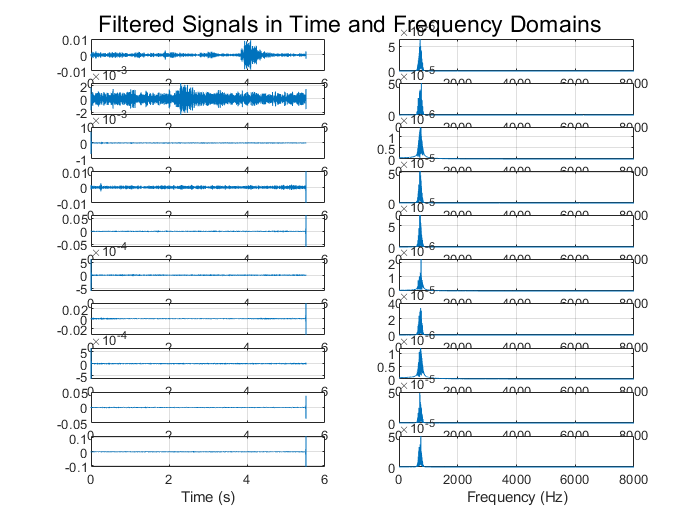

% Parameters
folderPath = 'second_test';        % Path to the folder containing audio files
Fs = 44100;                       % Sampling rate (Hz), adjust if needed
numSamples = 10;                  % Number of recorded signals
T = 1;                            % Duration of the signal segment to analyze (seconds)
N = Fs * T;                       % Number of samples in the segment
lowCutoff = 1970;                 % Lower cutoff frequency (Hz)
highCutoff = 2030;                % Upper cutoff frequency (Hz)

% Design a Bandpass Filter
bpFilter = designfilt('bandpassfir', ...
                      'StopbandFrequency1', lowCutoff - 500, ...
                      'PassbandFrequency1', lowCutoff, ...
                      'PassbandFrequency2', highCutoff, ...
                      'StopbandFrequency2', highCutoff + 500, ...
                      'StopbandAttenuation1', 60, ...
                      'StopbandAttenuation2', 60, ...
                      'PassbandRipple', 1, ...
                      'SampleRate', Fs);

% Create a Figure for Time and Frequency Domain Plots
figure;

% Loop Through Each Audio File
for i = 1:numSamples
    % Generate the Full File Path
    fileName = sprintf('sample%02d_record.wav', i);
    filePath = fullfile(folderPath, fileName);
    
    % Check if the File Exists
    if ~isfile(filePath)
        fprintf('File "%s" not found. Skipping...\n', filePath);
        continue;
    end
    
    % Load the Audio File
    [signal, Fs] = audioread(filePath);
    
    % Extract a Segment of Length 2T (2 Seconds)
    segmentLength = min(2 * N, length(signal));
    signal = signal(1:segmentLength, 1); % First channel only, if stereo
    
    % Apply Bandpass Filter
    filteredSignal = filtfilt(bpFilter, signal); % Zero-phase filtering
    
    % Compute FFT for Filtered Signal
    fftFiltered = abs(fft(filteredSignal, N)) / N; 
    
    % Create a Time Vector for 2T Duration
    time = (0:segmentLength - 1) / Fs;
    
    % Plot Time and Frequency Domain for Each Signal
    subplot(numSamples, 2, (i - 1) * 2 + 1);
    plot(time, filteredSignal);
    xlabel('Time (s)');
    %ylabel('Amplitude');
    %title(sprintf('Filtered Signal in Time Domain (Volume Level %02d)', i));
    grid on;

    subplot(numSamples, 2, (i - 1) * 2 + 2);
    frequency = (0:N/2-1) * (Fs / N); % Frequency vector for FFT
    plot(frequency, fftFiltered(1:N/2));
    xlabel('Frequency (Hz)');
    %ylabel('Amplitude');
    %title(sprintf('Filtered Signal in Frequency Domain (Volume Level %02d)', i));
    grid on;

    % Optionally, Save Filtered Signal to New File
    outputFileName = sprintf('filtered_bandpass_sample%02d_record.wav', i);
    outputFilePath = fullfile(folderPath, outputFileName);
    audiowrite(outputFilePath, filteredSignal, Fs);
end

% Adjust Figure Layout
sgtitle('Filtered Signals in Time and Frequency Domains');